# Decision Making Algorithm - Active & Passive Data

#### This script performs a user defined threshold check on two data inputs (SNR_input_1 & SNR_input_2).  SNR_input_1 is the preferred data source (i.e., Passive).  If SNR_input_1 data is => the threshold, this value is selected, if not the same check is completed on SNR_inpupt_2, if this meets the threshold then this value is selected. If both data sets do not meet the threshold the highest value is selected.

#### A counter increments each time an input is selected. The best case values are also stored for visualisation.

#### The result is output in total counts and the percentage of time each input was chosen.

#### THe data is also visualised in a plot, a scatter and a hybrid plot-scatter. 

User to define the data inputs for comparison

SNR_input_1 = passive_SNR;
SNR_input_2 = active_SNR;

Visualisation of Active & Passive SNR

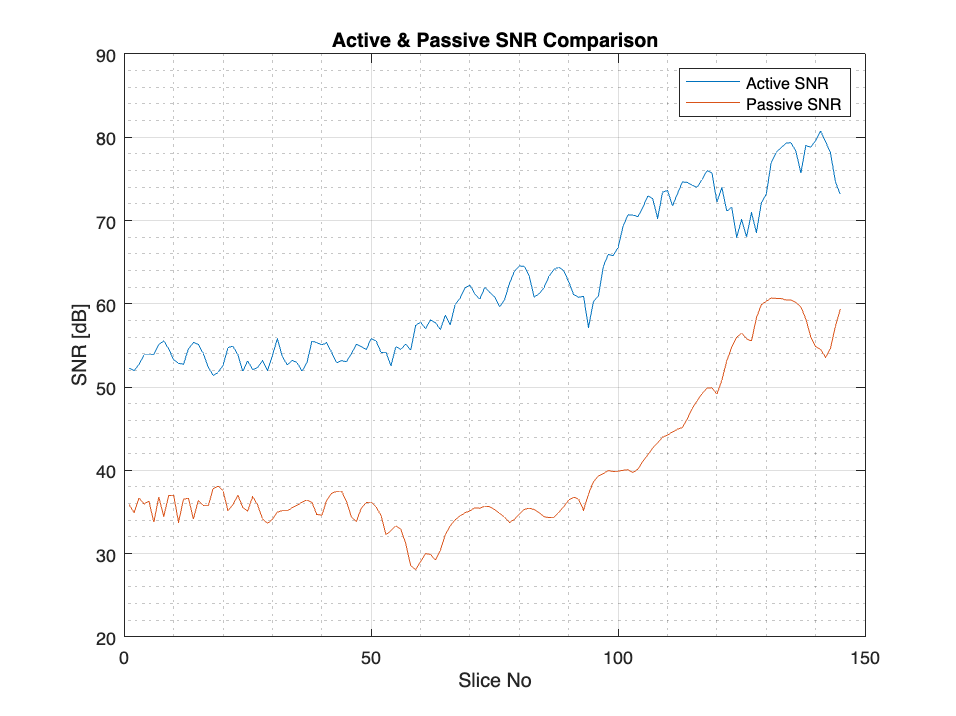

figure
% figure_title = ('Active & Passive SNR Comparison');
fig = figure;
plot(1:length(active_SNR), active_SNR, 'LineWidth', 0.5)
hold on
plot(1:length(passive_SNR), passive_SNR, 'LineWidth', 0.5)
hold off
% plot(1:length(active_SNR), active_SNR, ...
%     1:length(passive_SNR), passive_SNR, 'LineWidth', 2)
title('Active & Passive SNR Comparison');
ylabel('SNR [dB]');
xlabel('Slice No') ;
legend("Active SNR", 'Passive SNR')
grid on
%ylim([-max_doppler max_doppler]); % Doppler Limit
% xlim([-inf length(passive_SNR)]);   % Range Limit
grid minor

Introduce Decision Making

% Desired threshold
threshold = 40;

% Initialize a cell array to store the results
if length(SNR_input_1) == length(SNR_input_2)
    selected_input_value = zeros(1,length(SNR_input_1));
    selected_input_id = zeros(1,length(SNR_input_2));
    count_input_1 = 0;
    count_input_2 = 0;
else
    error('Inputs are not the same length.')
end

% Loop through each cell entry
for i = 1:length(SNR_input_1)
    % Threshold check for each cell entry
    if SNR_input_1(i) >= threshold
        selected_input_value(i) = SNR_input_1(i); % stores the value [dB]
        selected_input_id(i) = 1; % stores the input ID
        count_input_1 = count_input_1 + 1;
        % disp(['Input 1 selected for cell ' num2str(i) '.']);
    elseif SNR_input_2(i) >= threshold
        selected_input_value(i) = SNR_input_2(i); % stores the value [dB]
        selected_input_id(i) = 2; % stores the input ID
        count_input_2 = count_input_2 + 1;
        % disp(['Input 2 selected for cell ' num2str(i) '.']);
    else
        if SNR_input_1(i) > SNR_input_2(i)
            selected_input_value(i) = SNR_input_1(i); % stores the value [dB]
            selected_input_id(i) = 1; % stores the input ID
            count_input_1 = count_input_1 + 1;
            % disp(['Threshold not met. Input 1 selected for cell ' num2str(i) '.']);
        else
            selected_input_value(i) = SNR_input_2(i); % stores the value [dB]
            selected_input_id(i) = 2; % stores the input ID
            count_input_2 = count_input_2 + 1;
            % disp(['Threshold not met. Input 2 selected for cell ' num2str(i) '.']);
        end
    end
end

Result in Numbers

count_input_1

count_input_1 = 43

count_input_2

count_input_2 = 102

percent_usage_input_1 = (count_input_1 / length(SNR_input_1))*100

percent_usage_input_1 = 29.6552

percent_usage_input_2 = (count_input_2 / length(SNR_input_2))*100

percent_usage_input_2 = 70.3448

## Visualisation of Active, Passive & Threshold decision SNR

As a plot

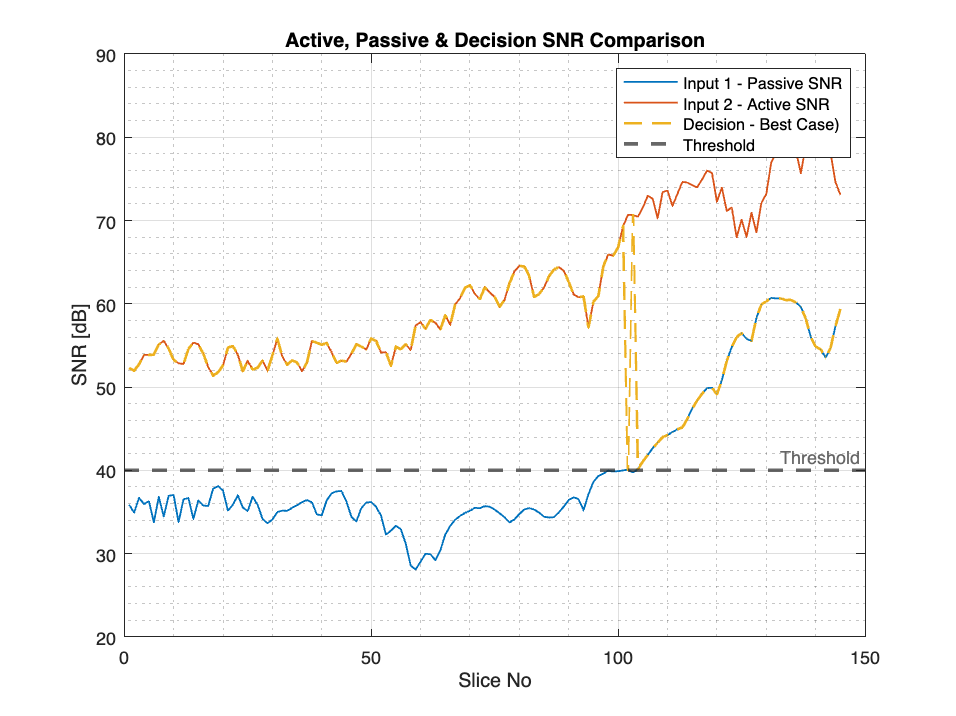

figure
% figure_title = ('Active & Passive SNR Comparison');
fig = figure;
% plot(1:length(active_SNR), active_SNR, ...
%     1:length(passive_SNR), passive_SNR, ...
%     1:length(selected_input_value), selected_input_value)
plot(1:length(SNR_input_1), SNR_input_1, 'LineWidth', 1)
hold on
plot(1:length(SNR_input_2), SNR_input_2, 'LineWidth', 1)
plot(1:length(selected_input_value), selected_input_value, '--', 'LineWidth', 1.5)

title('Active, Passive & Decision SNR Comparison');
ylabel('SNR [dB]');
xlabel('Slice No') ;
legend("Active SNR", 'Passive SNR', 'Decision (best case)')
grid on
%ylim([-max_doppler max_doppler]); % Doppler Limit
% xlim([-inf length(passive_SNR)]);   % Range Limit
grid minor
hold on

% Plot the threshold line
threshold_line = yline(threshold, '--', 'Threshold', 'LineWidth', 2);
legend("Input 1 - Passive SNR", 'Input 2 - Active SNR', 'Decision - Best Case)', 'Threshold')
hold off


sum(selected_input_id);


As a Scatter

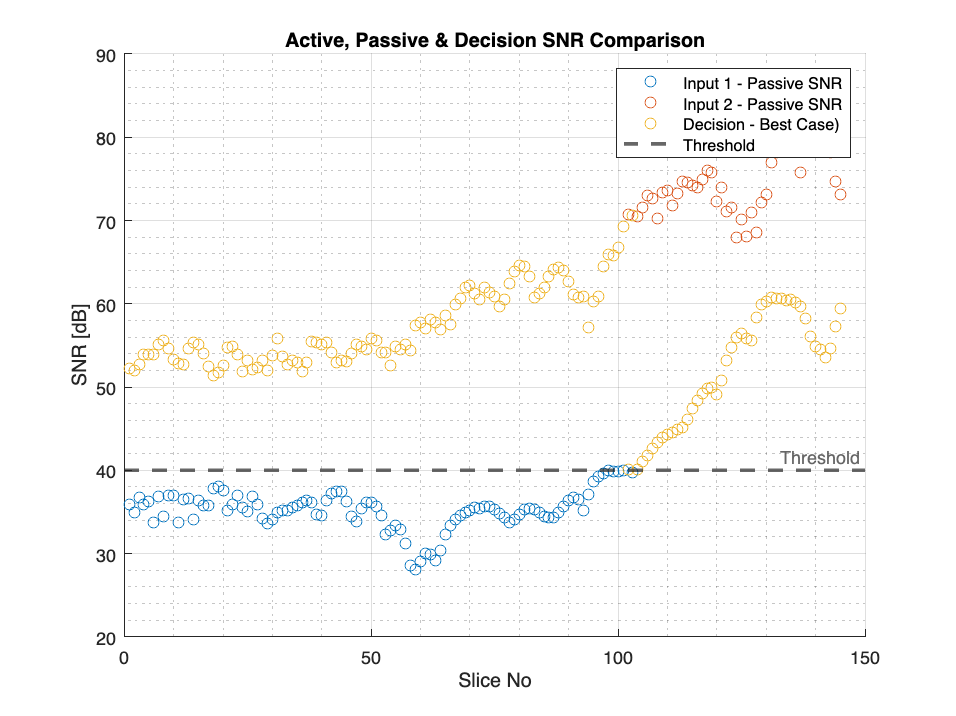

figure
scatter(1:length(SNR_input_1), SNR_input_1, 'LineWidth', 0.5)
hold on
scatter(1:length(SNR_input_2), SNR_input_2, 'LineWidth', 0.5)
scatter(1:length(selected_input_value), selected_input_value, 'LineWidth', 0.5)

title('Active, Passive & Decision SNR Comparison');
ylabel('SNR [dB]');
xlabel('Slice No') ;
legend("Active SNR", 'Passive SNR', 'Decision (best case)')
grid on
%ylim([-max_doppler max_doppler]); % Doppler Limit
% xlim([-inf length(passive_SNR)]);   % Range Limit
grid minor
hold on

% Plot the threshold line
threshold_line = yline(threshold, '--', 'Threshold', 'LineWidth', 2);
legend("Input 1 - Passive SNR", 'Input 2 - Passive SNR', 'Decision - Best Case)', 'Threshold')
hold off

As a hybrid Scatter

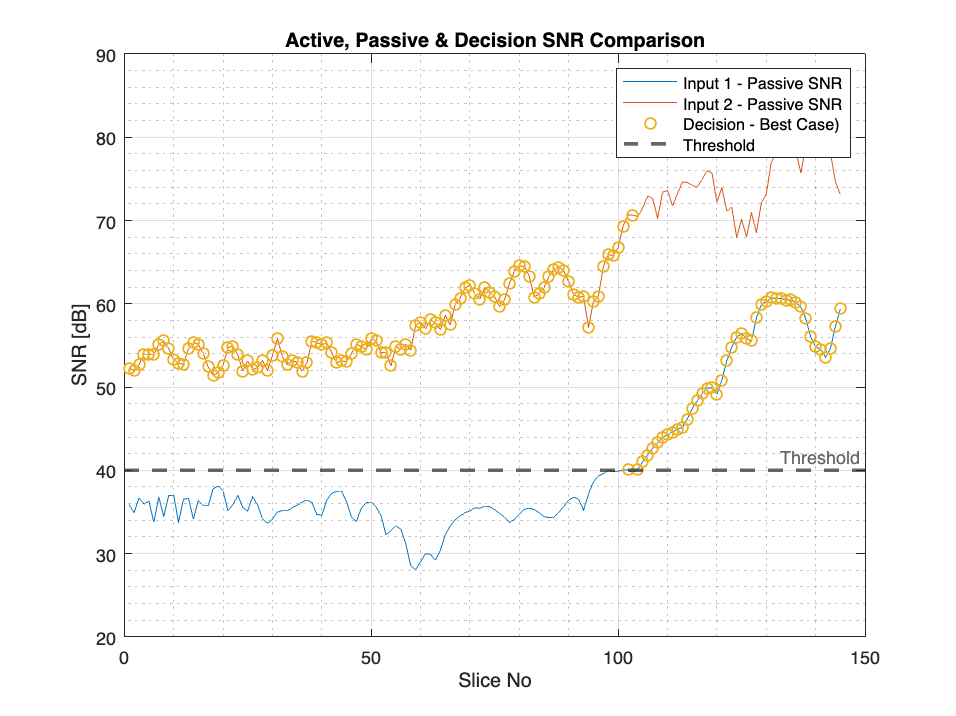

figure
plot(1:length(SNR_input_1), SNR_input_1, 'LineWidth', 0.5)
hold on
plot(1:length(SNR_input_2), SNR_input_2, 'LineWidth', 0.5)
scatter(1:length(selected_input_value), selected_input_value, 'LineWidth', 1)

title('Active, Passive & Decision SNR Comparison');
ylabel('SNR [dB]');
xlabel('Slice No') ;
legend("Active SNR", 'Passive SNR', 'Decision (best case)')
grid on
%ylim([-max_doppler max_doppler]); % Doppler Limit
% xlim([-inf length(passive_SNR)]);   % Range Limit
grid minor
hold on

% Plot the threshold line
threshold_line = yline(threshold, '--', 'Threshold', 'LineWidth', 2);
legend("Input 1 - Passive SNR", 'Input 2 - Passive SNR', 'Decision - Best Case)', 'Threshold')
hold off